clear, clc, format short g

load("dati_punto_2.mat");

## Parte 3

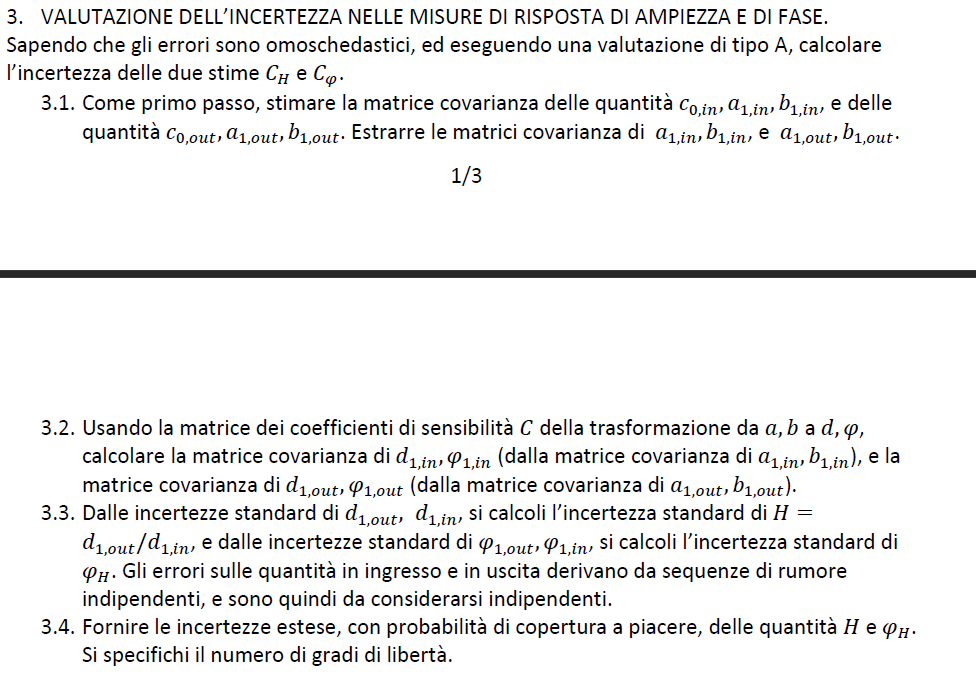

## Stima con valutazione di tipo A dell'incertezza

x_hat = A*theta_hat_x;

% stima dell'errore in ingresso
e_hat_x = xs - x_hat;

N_theta_x = length(theta_hat_x);

% Numero di gradi di libertà
nu = N-N_theta_x;

% Stima varianza in ingresso con incertezza di tipo A
sigma2_x = sum(e_hat_x.^2)/nu;


## Stima matrice covarianza in ingresso sapendo che gli errori sono omoschedastici

sigma_theta_x = sigma2_x*inv(A'*A);

% Estrazione della matrice covarianza in ingresso riferita ai due coefficienti della
% forma rettangolare indicati
sigma_theta_x_a1_b1 = sigma_theta_x(2:end, 2:end)

sigma_theta_x_a1_b1 =    7.8683e-05   7.3396e-08
   7.3396e-08    8.647e-05


## Stima con valutazione di tipo A della matrice covarianza in uscita

y_hat = A*theta_hat_y;

% stima errore in uscita
e_hat_y = ys - y_hat;

N_theta_y = length(theta_hat_y);

% gradi di libertà in uscita
nu = N-N_theta_y;

% stima varianza in uscita
sigma2_y = sum(e_hat_y.^2)/nu;

% stima matrice covarianza in uscita
sigma_theta_y = sigma2_y*inv(A'*A);

%estrazione matrice covarianza riferita ai parametri della forma
%rettangolare a1 e b1
sigma_theta_y_a1_b1 = sigma_theta_y(2:end, 2:end)

sigma_theta_y_a1_b1 =    8.2546e-05   7.6999e-08
   7.6999e-08   9.0715e-05


## Passaggio dalla matrice covarianza di a1_x e b1_x a quella di d1_x e phi_x

% Calcolo simbolico matrice C_d_phi noti a1, b1 e d1
syms a1_sym b1_sym as real

[C_sym,x_sym] = symbolic_computation(a1_sym, b1_sym);
C_sym

$$C\_sym = \left(\begin{array}{cc} \frac{a_{1,\mathrm{sym}}}{\sqrt{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}}} & \frac{b_{1,\mathrm{sym}}}{\sqrt{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}}}\\ -\frac{b_{1,\mathrm{sym}}}{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}} & \frac{a_{1,\mathrm{sym}}}{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}} \end{array}\right)$$


% Definisco i vettori dei valori effettivamente misurati
x_in = [a1_hat_x, b1_hat_x];
x_out = [a1_hat_y, b1_hat_y];

C_d_phi_x = double(subs(C_sym,x_sym,x_in))

C_d_phi_x =      -0.72089     -0.69305
      0.13929     -0.14489


sigma_d_phi_x = C_d_phi_x*sigma_theta_x_a1_b1*C_d_phi_x';

% estrazione incertezze standard assolute di d1 e ph in ingresso
u_d1_x = sqrt(sigma_d_phi_x(1,1))

u_d1_x =     0.0090828


u_phi_x = sqrt(sigma_d_phi_x(2,2))

u_phi_x =     0.0018273


## Passaggio dalla matrice covarianza di a1_y e b1_y a quella di d1_y e phi_y

C_d_phi_y = double(subs(C_sym,x_sym,x_out))

C_d_phi_y =      -0.81803     -0.57518
      0.11712     -0.16658


sigma_d_phi_y = C_d_phi_y*sigma_theta_y_a1_b1*C_d_phi_y';

% estrazione incertezze standard assolute di d1 e ph in uscita
u_d1_y = sqrt(sigma_d_phi_y(1,1))

u_d1_y =     0.0092369


u_phi_y = sqrt(sigma_d_phi_y(2,2))

u_phi_y =     0.0019096


## Tabella delle incertezze

rows = [{'INPUT'},{'OUTPUT'}];
u_d1=[u_d1_x;u_d1_y];
u_phi=[u_phi_x;u_phi_y];
T = table(u_d1,u_phi,'RowNames',rows)

T = 2×2 table
                u_d1         u_phi  
              _________    _________

    INPUT     0.0090828    0.0018273
    OUTPUT    0.0092369    0.0019096


## Calcolo incertezza standard su H e phi

H = d1_hat_y/d1_hat_x

H =         0.987



% H è una funzione monomia, di conseguenza i coefficienti di sensibilità
% relativi sono gli esponenti delle variabili nella funzione
Cr_h = [1 -1];

% calcolo rispettive incertezze relative in uscita ed in entrata note le
% assolute estratte prima

[sigmar_H, ur_H] = create_sigma_matrix(u_d1_y/abs(d1_hat_y), u_d1_x/abs(d1_hat_x), Cr_h);

% stima incertezza assoluta nota la relativa ed il modulo della risposta in
% ampiezza H = d1_out/d1_in
u_H = ur_H*abs(H)

u_H =     0.0025871



% calcolo risposta di fase 

phi = phi1_hat_y - phi1_hat_x

phi =      -0.15289



% essendo phi un polinomio, i coefficienti di sensibilità relativi sono i
% coefficienti del polinomio

C_phi = [1 -1];


[sigma_phi, u_phi] = create_sigma_matrix(u_phi_y, u_phi_x, C_phi);

u_phi

u_phi =      0.002643


## Calcolo incertezze estese con cp = 95%


% dato che la valutazione dell'incertezza è di tipo A si utilizza la
% distribuzione t di Student
k = tinv((1+0.95)/2, nu)

k =        1.9623



U_H = k*u_H

U_H =     0.0050767



U_phi = k*u_phi

U_phi =     0.0051865



% NB: essendo N_theta molto piccolo, nu tende a N quindi K assume un valore
% molto simile a quello calcolato usando la funzione norminv nel caso di
% valutazione dell'incertezza di tipo B

## Analizzo le incertezze di H e PHI

rows1 = [{'H'},{'PHI'}];
u = [u_H;u_phi];
U_95 = [U_H;U_phi];
misure = [H;phi];
T1 = table(misure,u,U_95,'rowNames',rows1)

T1 = 2×3 table
            misure         u          U_95   
           ________    _________    _________

    H         0.987    0.0025871    0.0050767
    PHI    -0.15289     0.002643    0.0051865



save dati_punto_3 U_H U_phi H phi ur_H C_H C_phi u_phi R fx
